# Actividad 7.1 (Waypoints)

Marcos Allen Martínez Cortés

A01737939

El código simula el movimiento de un robot diferencial que sigue una trayectoria definida por puntos de referencia (waypoints). Podemos comprender el código en sicnco secciones:

- Definición del vehículo mediante sus dimensiones físicas como el radio de las ruedas y la distancia entre ellas.

- Definición de los parámetros de simulación como el tiempo de muestreo, el vector de tiempo de simulación, la pose (posición y orientación) inicial del robot, los waypoints que indican la trayectoria y el visualizador para la interfaz gráfica.

- Configurador del controlador utilizando toolboxes de MATLAB. Este controlador nos permite mediante su algoritmo ir calculando la posición actual del robot con un punto objetivo sobre la trayectoria, situado mirando al frente (look-ahead).

- Bucle de simulación: donde actúa el controlador, la cinemática inversa y directa del robot, la transformación del robot al mundo, integración con Euler para actualizar la posición y la visualización gráfica.

Los parámetros a modificar fueron los siguientes:

- Waypoints: estableciendo los puntos de referencia de la trayectoria.

- tVec: es el vector de tiempo de la simulación, y depende tanto de la trayectoria como de las velocidades del robot.

- initPose: es la pose inicial del robot, que indica su posición y orientación iniciales; si es cercana al primer waypoint o es el primer waypoint, el robot continuará con la trayectoria de manera fluida, pero si está lejos del waypoint, necesitará un mayor tiempo de reacción y podrá desviarse de la trayectoria.

- LookaheadDistance: es la distancia a la que el robot "mira" hacia adelante para calcular su giro. Con valores altos el robot suaviza la trayectoria, lo que es bueno para tramos rectos o trayectorias con curvas abiertas; pero, si es muy alta el robot no pasa correctamente por los waypoints. Con valores bajos, el robot intenta seguir la trayectoria con mucha precisión, lo cual es útil para trayectorias complejas o con curvas cerradas; pero, cuando el valor es muy bajo el robot comienza a oscilar.

- DesiredLinearVelocity: es la velocidad lineal del robot; para trayectorias largas y con muchos tramos rectos el valor puede aumentarse para reducir el tiempo que dura la trayectoria; pero para trayectorias con muchas curvas o curvas cerradas, se debe reducir, ya que en caso contrario el robot de saldrá de la ruta y/o no pasará por los waypoints.

- MaxAngularVelocity: es el límite de la velocidad angular del robot. En trayectorias con pocas curvas o curvas suaves un valor bajo es suficiente; pero en trayectorias con curvas cerradas, la velocidad angular debe ser muy alta, ya que el robot debe ser capaz de rotar rápidamente para alinearse con el siguiente waypoint sin desviarse.

De este modo, se fueron realizando pruebas, con las que se fue observando el comportamiento descrito anteriormente y con lo que se pudo ir ajustando los parámetros para generar el seguimiento de los waypoints.

**Implementar **el código requerido para generar el seguimiento de los siguientes waypoints (puntos de referencia), ajustando el tiempo de muestreo: **“****sampleTime****”,** vector de tiempo: **“****tVec****”,** pose inicial: **“****initPose****”,** y los waypoints: **“****waypoints****”**

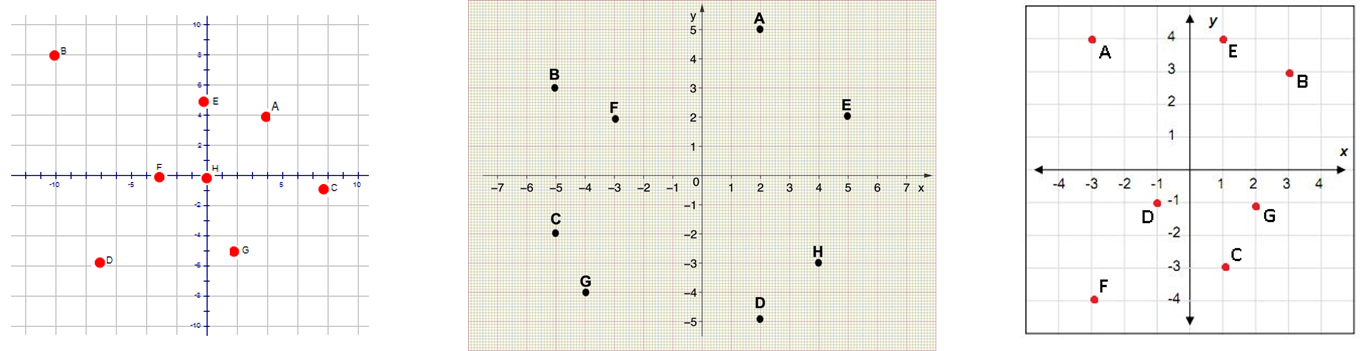

Para el primer conjunto de waypoints se comenzó por establecer el orden de los waypoints de tal manera que fueran cercanos entre sí, lo cual fue se suma importancia para facilitarle el seguimiento al robot para que no se desviará de la trayectoria.

Después se estableció la pose inicial y comenzaron a modificarse los parámetros del controlador:

- LookaheadDistance de 1.25 para tener una trayectoria suave pero pasando por los waypoints.

- DesiredLinearVelocity de 1.5 para que la trayectoria fuera rápida.

- MaxAngularVelocity de 0.75 para tener una trayectoria suave, con los giros necesarios.

Finalmente, se ajustó el tiempo de la simulación a 35 segundos para que tuviera tiempo de pasar todos los waypoints.

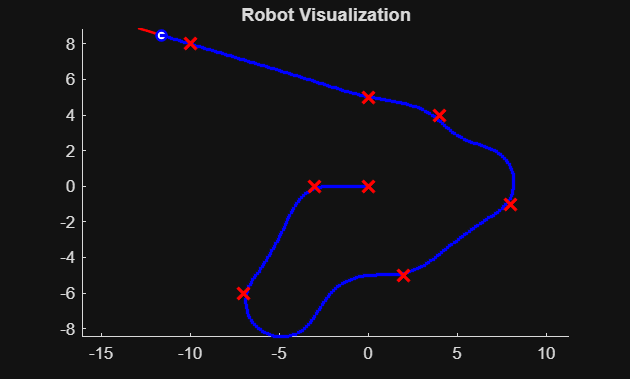

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:35;         % Time array

initPose = [0;0;pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [0,0; -3,0; -7,-6; 2,-5; 8,-1; 4,4; 0,5; -10,8];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 1.25;
controller.DesiredLinearVelocity = 1.5;
controller.MaxAngularVelocity = 0.75;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Para el segundo conjunto de waypoints, se realizó de forma similar al anterior. Se estableció el orden de los waypoints, la pose inicial y después los parámetros del controlador:

- LookaheadDistance de 0.8 para tener una trayectoria relativamente suave, pero con mayor precisión para pasar por los waypoints.

- DesiredLinearVelocity de 1 para que la trayectoria fuera relativamente rápida.

- MaxAngularVelocity de 2 para poder realizar los giros necesarios, aunque no fueran tan suaves.

Finalmente, se ajustó el tiempo de la simulación a 30 segundos.

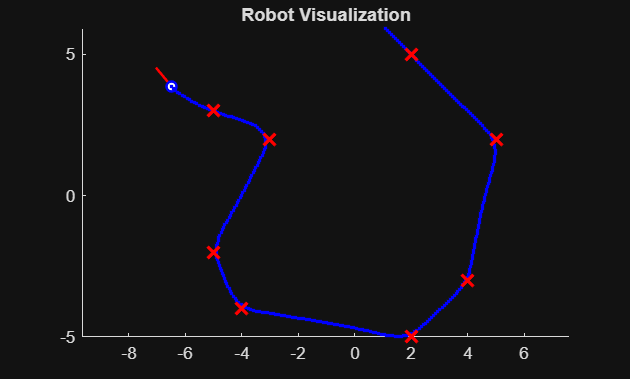

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:30;         % Time array

initPose = [1;6;-0.25*pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [2,5; 5,2; 4,-3; 2,-5; -4,-4; -5,-2; -3,2; -5,3];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.8;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 2;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Para el tercer conjunto de waypoints, el procedimiento fue similar a los anteriores. Se estableció el orden de los waypoints, la pose inicial y después los parámetros del controlador:

- LookaheadDistance de 0.6 para tener una trayectoria con precisión, para pasar por todos los waypoints.

- DesiredLinearVelocity de 1 para que la trayectoria fuera relativamente rápida.

- MaxAngularVelocity de 0.6 para poder realizar los giros necesarios y de forma suave.

Finalmente, se ajustó el tiempo de la simulación a 27.5 segundos.

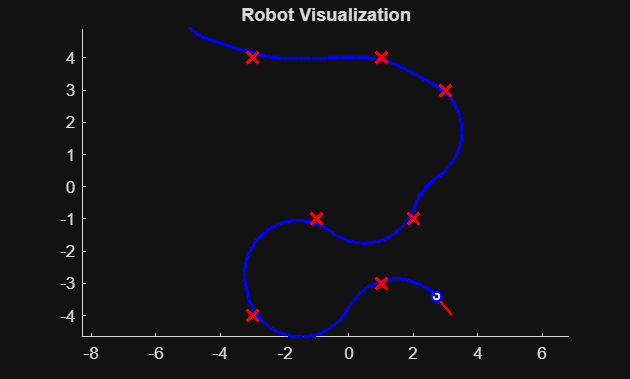

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:27.5;         % Time array

initPose = [-5;5;-0.25*pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [-3,4; 1,4; 3,3; 2,-1; -1,-1; -3,-4; 1,-3];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.6;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 0.6;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

**Generar** los waypoints (puntos de referencia) necesarios para obtener las siguientes trayectorias, ajustando el tiempo de muestreo: **“****sampleTime****”,** vector de tiempo: **“****tVec****”,** pose inicial: **“****initPose****”,** y los waypoints: **“****waypoints****”**

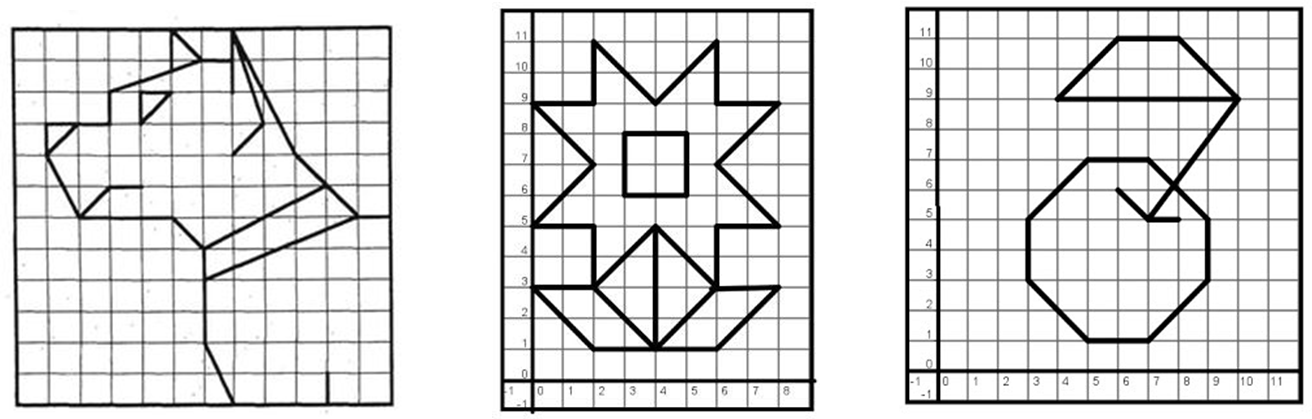

Para la primera figura, se comenzó por extraer manualmmente los waypoints necesarios, que permitieran que la trayectoria construyera la figura, con lo que se extrajeron primero los waypoints de los vértices significativos y después waypoints intermedios  de tal manera que el conjunto de waypoints fueran cercanos entre sí, lo cual fue se suma importancia para facilitarle el seguimiento al robot para que no se desviará de la trayectoria.

Después se estableció la pose inicial y comenzaron a modificarse los parámetros del controlador:

- LookaheadDistance de 0.25 para tener una trayectoria con precisión.

- DesiredLinearVelocity de 0.4 para que la trayectoria fuera lenta, y el robot pudiera reaccionar ante los cambios de dirección.

- MaxAngularVelocity de 10 para poder realizar los giros bruscos, rotando rápidamente.

Fue importante la combinación de una velocidad lineal baja y una velocidad angular alta, porque (junto con el lookahead bajo) permitió poder realizar las líneas rectas y los giros bruscos de la figura.

Finalmente, se ajustó el tiempo de la simulación a 215 segundos para que el robot tuviera tiempo de pasar todos los waypoints, con las velocidades asignadas.

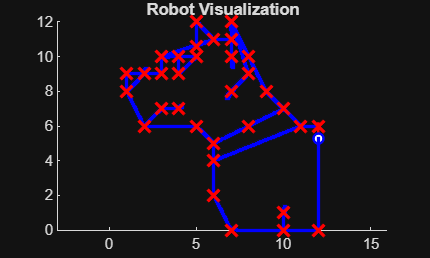

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:215;         % Time array

initPose = [12;6;pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [12,6; 11,6; 10,7; 8,6; 6,5; 6,4; 11,6; 9,8; 8,10; 7,12; 8,9; 7,8; ...
             8,9; 7,12; 7,10; 7,11; 6,11; 5,10.6; 5,12; 6,11; 3,10; 5,10; 4,9; ...
             4,10; 3,10; 3,9; 1,9; 1,8; 2,9; 1,8; 2,6; 3,7; 4,7; 3,7; 2,6; 5,6; ...
             6,5; 6,2; 7,0; 10,0; 10,1; 10,0; 12,0; 12,6];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.25;
controller.DesiredLinearVelocity = 0.4;
controller.MaxAngularVelocity = 10;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Para la segunda figura, se siguió un procedimiento similar al anterior. Comenzando con la extracción de los waypoints, después estableciendo la pose inicial y siguiendo con la modificación de los parámetros del controlador:

- LookaheadDistance de 0.3 para tener una trayectoria con precisión.

- DesiredLinearVelocity de 0.5 para que la trayectoria fuera lenta, y el robot pudiera reaccionar ante los cambios de dirección.

- MaxAngularVelocity de 5.5 para poder realizar los giros bruscos, rotando rápidamente.

Fue importante la combinación de una velocidad lineal baja y una velocidad angular alta, porque (junto con el lookahead bajo) permitió poder realizar las líneas rectas y los giros bruscos de la figura.

Finalmente, se ajustó el tiempo de la simulación a 140 segundos.

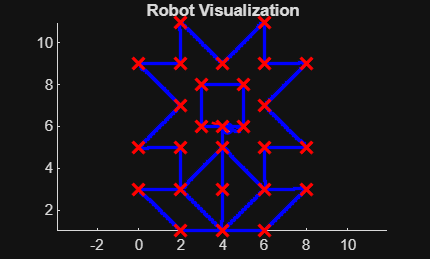

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:140;         % Time array

initPose = [4;1;0.75*pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,1; 2,3; 0,3; 2,1; 4,1; 6,1; 8,3; 6,3; 4,1; 4,3; 4,5; 6,3; ...
             6,5; 8,5; 6,7; 8,9; 6,9; 6,11; 4,9; 2,11; 2,9; 0,9; ...
             2,7; 0,5; 2,5; 2,3; 4,5; 4,6; 5,6; 5,8; 3,8; 3,6; 4,6];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.3;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 5.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Para la tercera figura, se siguió un procedimiento similar a los anteriores. Comenzando con la extracción de los waypoints, después estableciendo la pose inicial y siguiendo con la modificación de los parámetros del controlador:

- LookaheadDistance de 0.35 para tener una trayectoria con precisión.

- DesiredLinearVelocity de 0.5 para que la trayectoria fuera lenta, y el robot pudiera reaccionar ante los cambios de dirección.

- MaxAngularVelocity de 8 para poder realizar los giros bruscos, rotando rápidamente.

Fue importante la combinación de una velocidad lineal baja y una velocidad angular alta, porque (junto con el lookahead bajo) permitió poder realizar las líneas rectas y los giros bruscos de la figura.

Finalmente, se ajustó el tiempo de la simulación a 84 segundos.

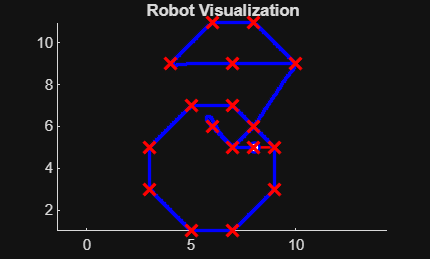

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:84;         % Time array

initPose = [10;9;0.75*pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [10,9; 8,11; 6,11; 4,9; 7,9; 10,9; 8,6; 7,7; 5,7; 3,5; ...
             3,3; 5,1; 7,1; 9,3; 9,5; 8,6; 7,5; 6,6; 7,5; 8,5];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 8;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end